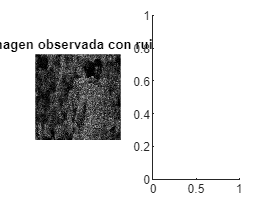

% Cargar la imagen observada con ruido (simulada)
imagen_observada = imread('im_3_level_10.png'); % Debes tener tu propia imagen con ruido

% Convertir la imagen a escala de grises
imagen_observada = double(im2gray(imagen_observada));

% Tamaño de la imagen
[alto, ancho] = size(imagen_observada);

% Parámetros ADMM
max_iter = 100;  % Número máximo de iteraciones
rho = 1;         % Parámetro de ajuste para actualización de multiplicadores de Lagrange

% Función de verosimilitud negativa (distribución de Poisson)
f = @(x) -sum(sum(imagen_observada .* log(x) - x));

% Función de penalización para la restricción de positividad (g(z) = I(z >= 0))
g = @(z) sum(sum(z(z<0).^2));

% Inicialización
x = zeros(alto, ancho); % Suponemos una imagen inicial constante
z = x; % Variables auxiliares
u = zeros(alto, ancho); % Multiplicadores de Lagrange inicializados en cero

% Implementación del algoritmo ADMM
for iter = 1:max_iter
    % Actualización de "x" (minimizar la función de verosimilitud y términos de Lagrange)
    x = exp((imagen_observada + rho*(z-u)) / (1+rho));
    
    % Actualización de "z" (minimizar la función de penalización y términos de Lagrange)
    z_antiguo = z;
    z = max(0, x + u);
    
    % Actualización de los multiplicadores de Lagrange "u"
    u = u + x - z;
    
    % Comprobar convergencia
    convergencia = norm(z - z_antiguo, 'fro') / norm(z_antiguo, 'fro');
    if convergencia < 1e-6
        break;
    end
end

% Mostrar resultados
figure;
subplot(1, 2, 1);
imshow(imagen_observada, []);
title('Imagen observada con ruido');

subplot(1, 2, 2);

imshow(x, []);

Error using imageDisplayValidateParams
Expected input number 2, [LOW HIGH], to be non-NaN.

Error in images.internal.checkDisplayRange (line 10)
validateattributes(display_range, {'numeric'},...

Error in images.internal.imageDisplayValidateParams (

title('Imagen reconstruida');